# Distortion, noise, and strain

This is a revision of DNaS_1.mlx. In this live script, the developments in all the previous major scripts will be applied to study the effects of noise in elucidating the total distortion using the Lawler-Fujita algorithm and how this combination affects the calculated physical strain according to Gao et al. (2017)'s method.

Let's define the initial parameters. If new to this live script, I suggest you change the values here and here only.

#### Image specifications

image_length = 256; % [pixel]
image_height = 256; % [pixel]
atom_diameter = 8; % [pixel]

lambda = 0.2; % [atom^-1]

Q_x = [1 0]; % [atom^-1]
Q_y = [-Q_x(2) Q_x(1)]; % just to ensure orthogonality

confidence_level = 0.9999999;

#### Distortion parameters

drift      =  [2 2]; % [atom/scan]
hysteresis =  [2 2]; % [atom]
creep      =  [2 2]; % [atom]

#### Noise parameters

noise_minimumLength = 10; % [atom]
noise_stdMagnitude = 1; % [atom]

Pre-processing the inputs, converting units. You might probably would't want to edit these.

lambda = lambda*2*pi/atom_diameter;
Q_x = Q_x * 2*pi / (norm(Q_x)*atom_diameter);
Q_y = Q_y * 2*pi / (norm(Q_y)*atom_diameter);
zscore = zscorer(confidence_level);

## 1    Adding distortion

The perfect square lattice is distorted according to the Lawler et al. (2010) paper with an atom centered at the origin (0,0) — matrix indices (1,1) for MATLAB.

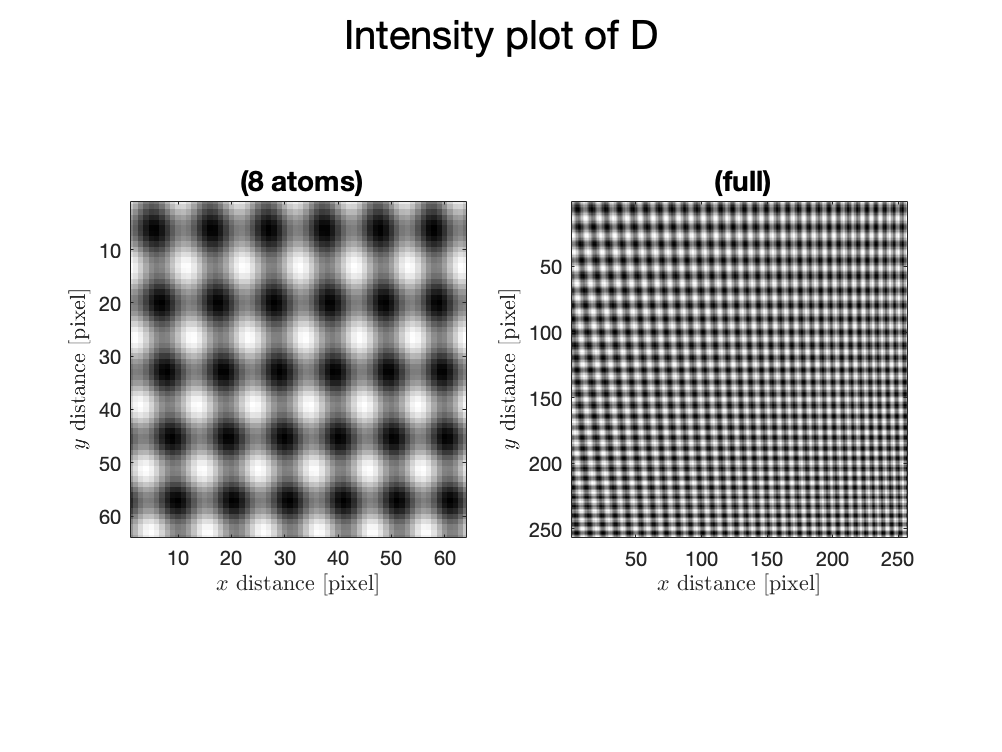

u = uCreate(image_height,image_length,atom_diameter,drift,hysteresis,creep);

lattice = normies(uTransform(u,Q_x,Q_y))*atom_diameter/2; % check the sign of u in uTransform()
comboPlot(lattice,"D",atom_diameter);

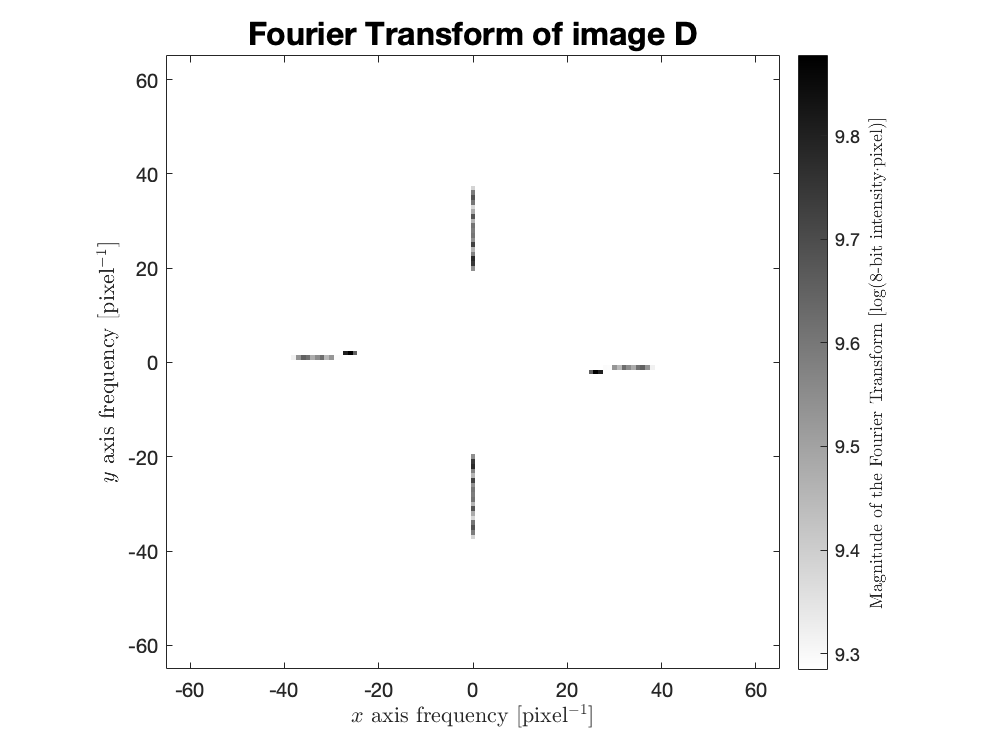

lattice_fft = myFFT(lattice,"D",[0.94 1]);


% ulattice = imwarp(lattice,u);
% comboPlot(ulattice,"uD",atom_diameter);
% ulattice_fft = myFFT(ulattice,"uD",[0.98 1]);

## 2    Adding noise

Noise is added to the lattice created above with an average magnitude and undulation length specified in the first code cell.

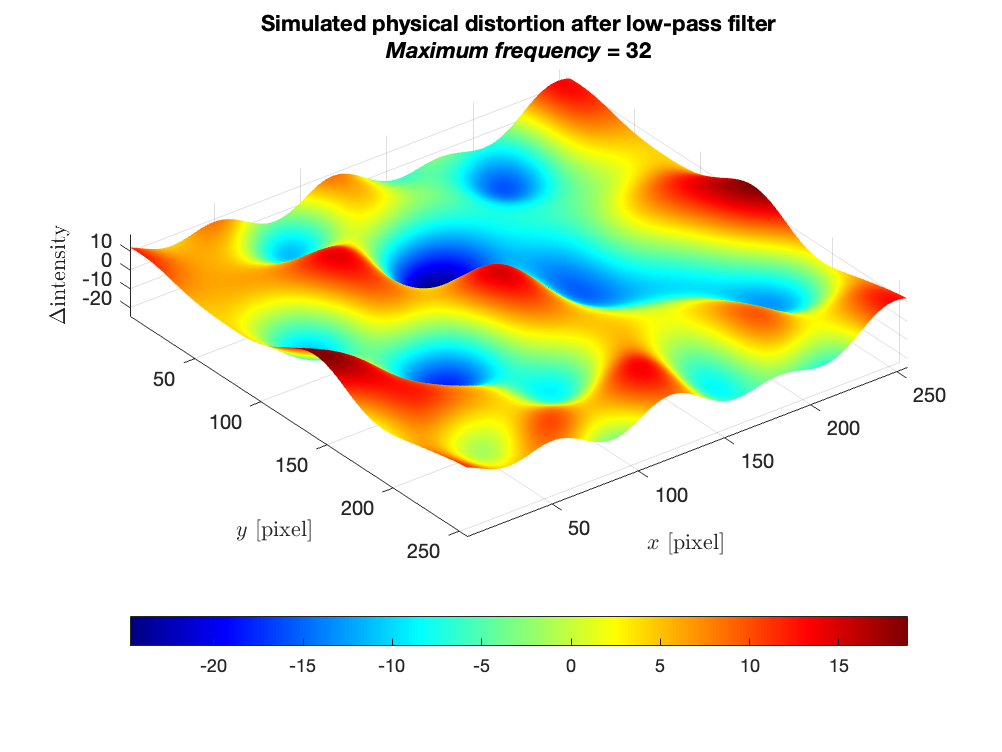

noise = noiseCreate(image_height,image_length,atom_diameter,noise_minimumLength,noise_stdMagnitude);
noisePlot(image_height,image_length,noise,[],atom_diameter);

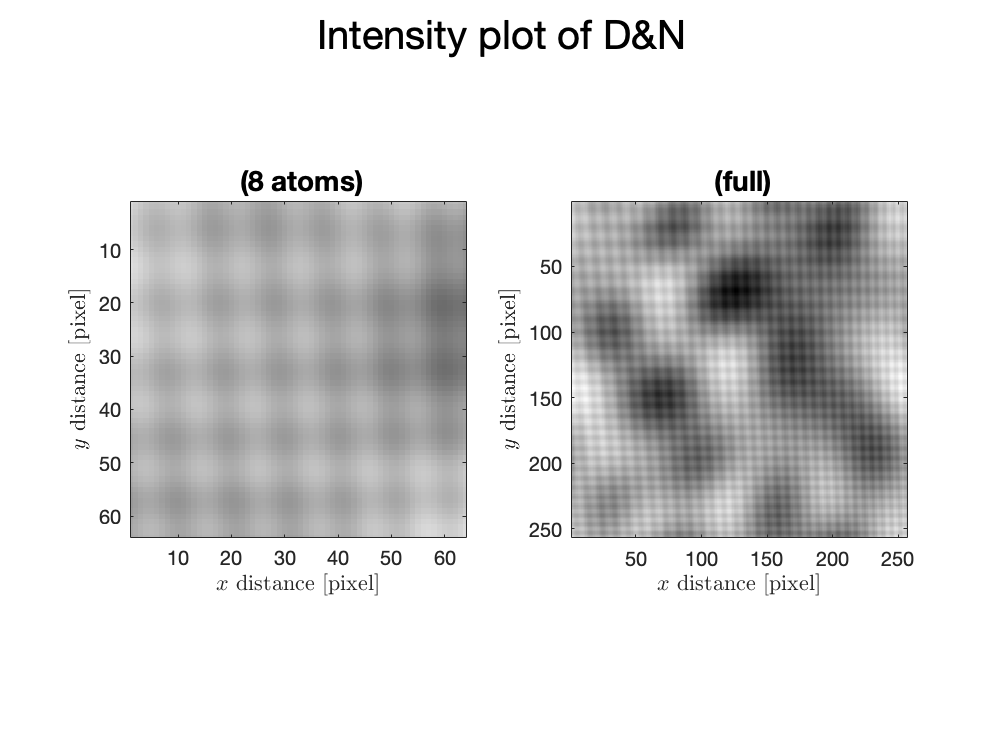


nlattice = lattice+noise;
comboPlot(nlattice,"D&N",atom_diameter);

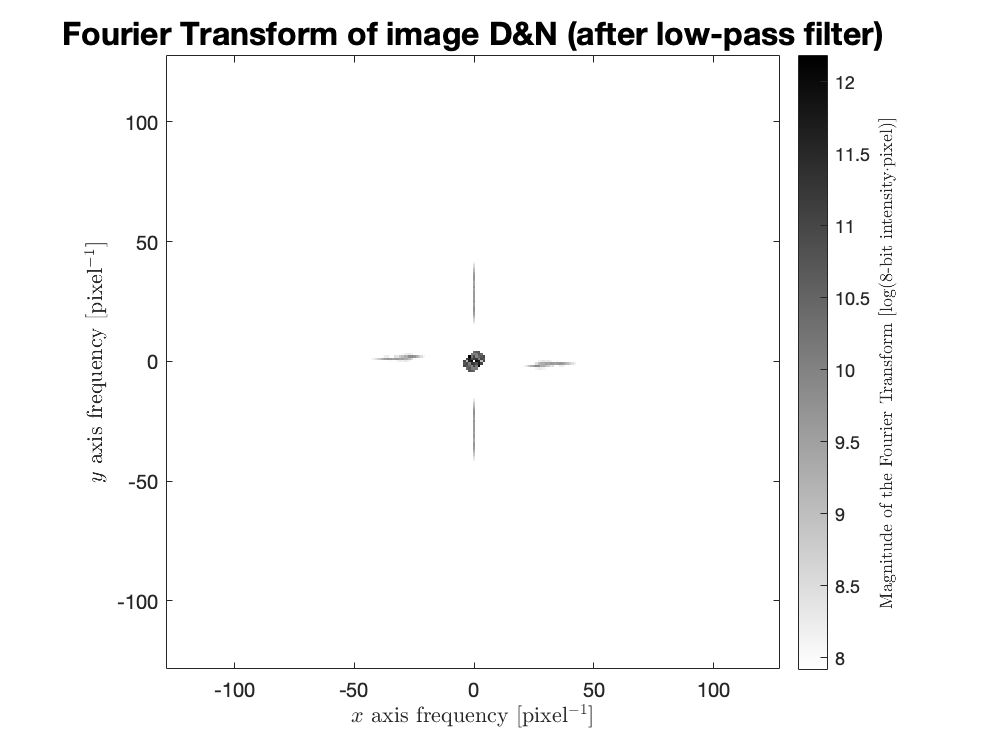

nlattice_fft = myFFT(nlattice,"D&N",[],atom_diameter/100); % just for full display

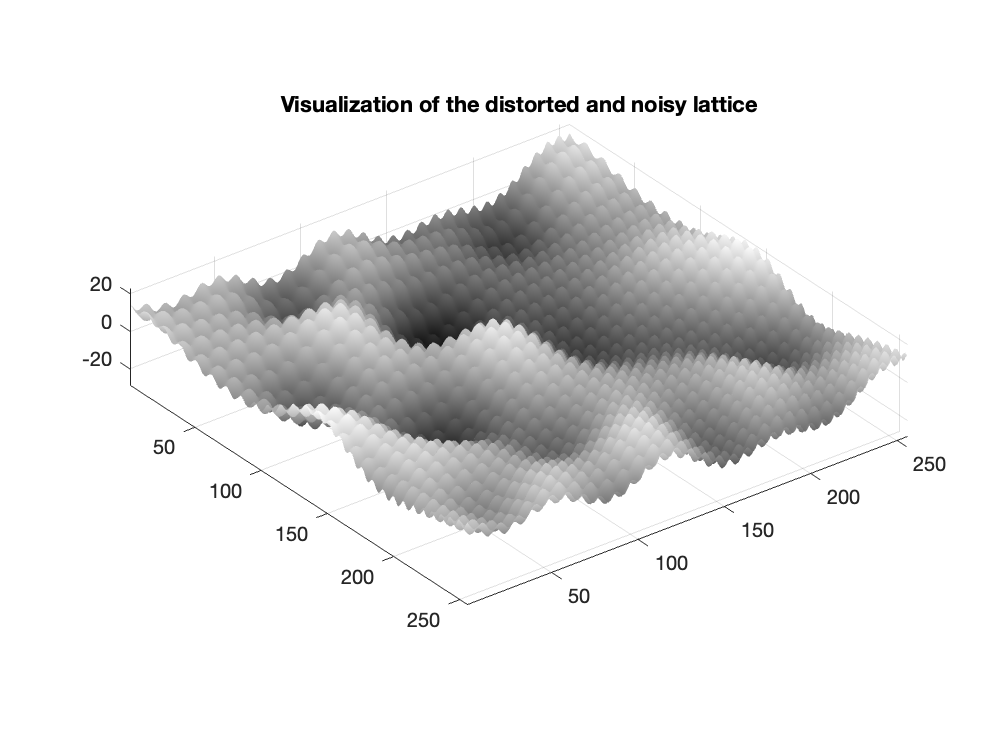


surf(nlattice);
shading interp;
axis equal;
set(gca,"YDir","reverse");
colormap(gray);
title("Visualization of the distorted and noisy lattice");

## 3    Calculating total distortion

Using the Lawler-Fujita algorithm, the total distortion as the sum of the imaging distortion and the physical strain, $\vec{u}_{calc}=\vec{d}+\vec{s}$, is calculated. The effects of noise and the magnitude and type of tolerable distortion could be studied using the previous and the following code.

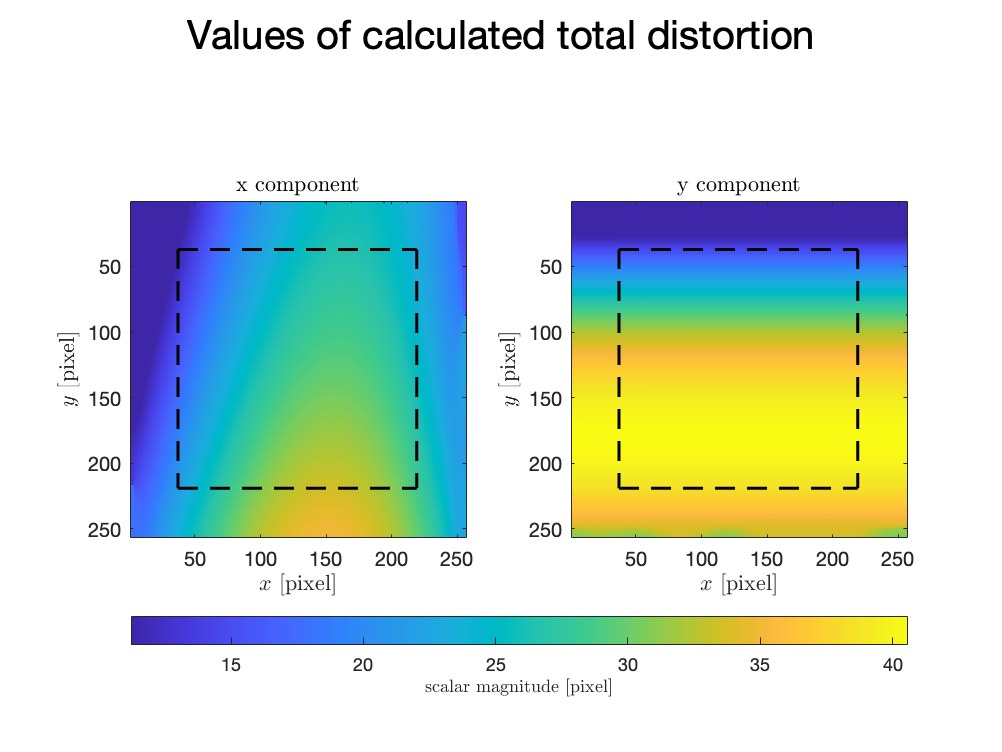

ucalc = myConv(nlattice,Q_x,Q_y,lambda,zscore,true); % true as last argument to plot u_x and u_y

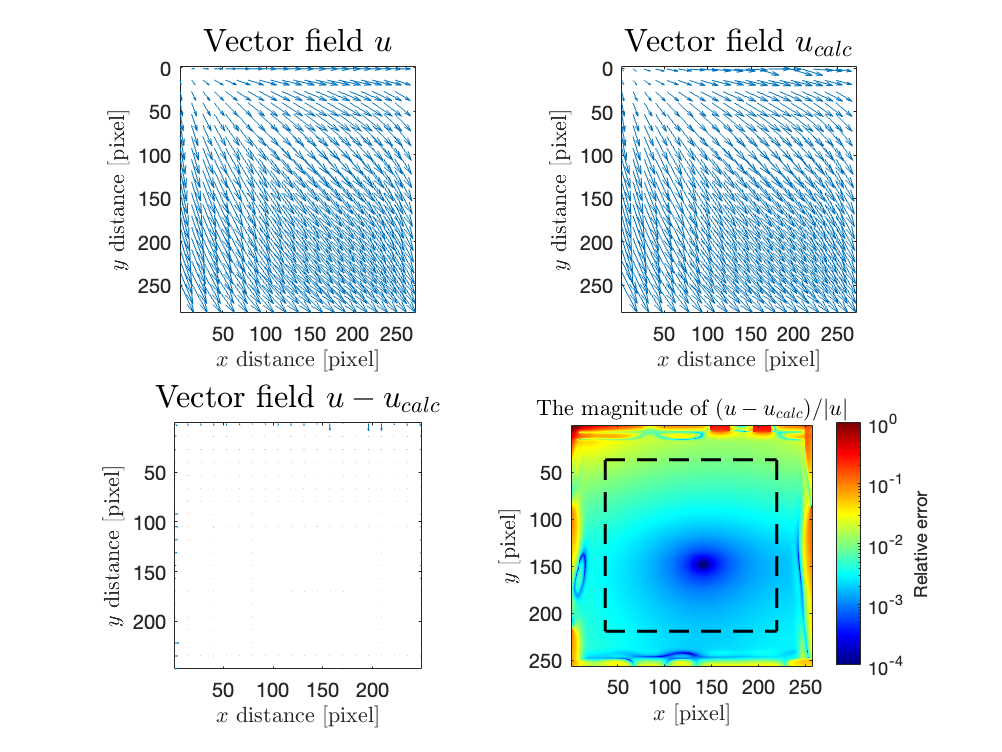


uComboPlot(u,ucalc,lambda,zscore);


if image_length-2*ceil(zscore/lambda)<=0 && image_height-2*ceil(zscore/lambda)<=0
    error("ERROR! No pixels without padded zeros remain.");
else
    npixel = (image_length-2*ceil(zscore/lambda))*(image_height-2*ceil(zscore/lambda));
    % the number of pixels averaged
    disp("Number of pixels averaged: " + npixel + " (" + ...
        npixel/(image_length*image_height)*100 + "%)");
end

Number of pixels averaged: 33124 (50.5432%)



[meanErr, stdErr] = uCompare(u,ucalc,lambda);
disp("Error is: " + meanErr + "+/-" + stdErr*zscore + " (" + confidence_level*100 + "% confidence)");

Error is: 0.0046357+/-0.026192 (100% confidence)


disp("Total error is: " + (meanErr+stdErr*zscore) + " (" + confidence_level*100 + "% confidence)");

Total error is: 0.030828 (100% confidence)


disp("Errors are relative unless stated otherwise.");

Errors are relative unless stated otherwise.


Try undistorting the distorted image using imwarp() and the calculated displacement field.

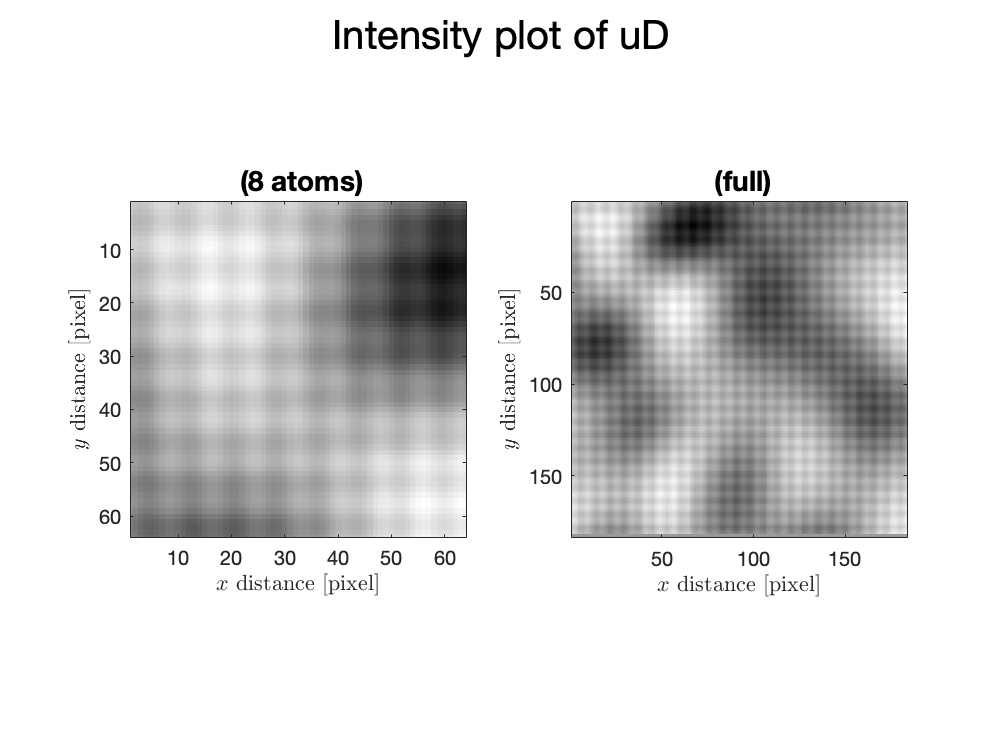

ucalc(isnan(ucalc)) = 0;
ulattice = imwarp(nlattice,ucalc);
zed = ceil(zscore/lambda);
ulattice = ulattice(zed:image_height-zed,zed:image_length-zed);
comboPlot(ulattice,"uD",atom_diameter);

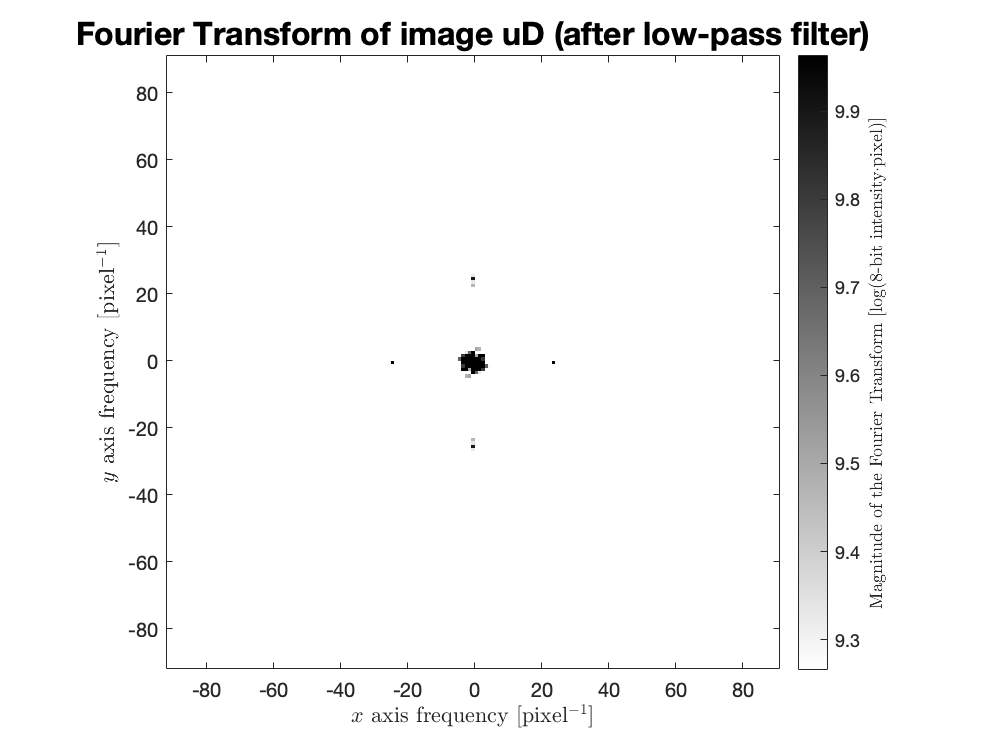

ulattice_fft = myFFT(ulattice,"uD",[9.3/11.4 10/11.4],atom_diameter/100);

## 4    Calculating physical strain

From the equation given above, the physical strain can be obtained by subtracting the smooth, third-digree polynomial imaging distortion from the total distortion.

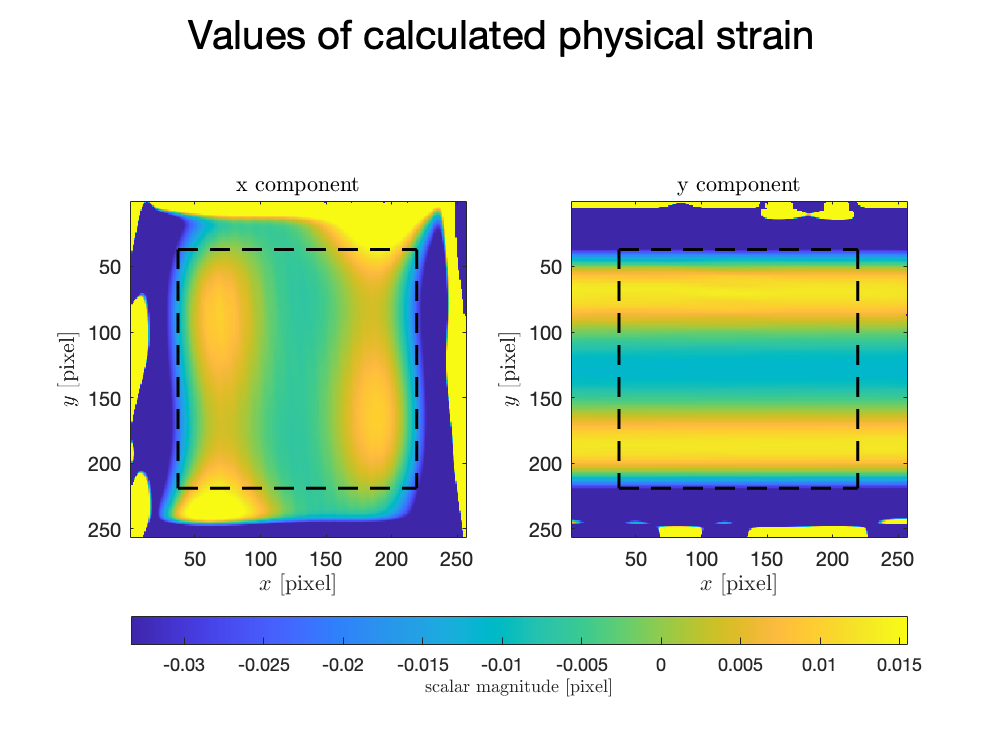

[fitresultx, gofx,outputx] = createFit(ucalc(:,:,1), lambda,zscore);
% fitPlot(fitresultx, ucalc(:,:,1), "$u_x$", lambda,zscore);
[fitresulty, gofy,outputy] = createFit(ucalc(:,:,2), lambda,zscore);
% fitPlot(fitresulty, ucalc(:,:,2), "$u_y$", lambda,zscore);

resx = reshape(outputx.residuals,image_height-2*ceil(zscore/lambda)+1,[]);
resy = reshape(outputy.residuals,image_height-2*ceil(zscore/lambda)+1,[]);
mu = zeros(2,1); sigma = zeros(2,1);
mu(1) = mean(resx,"all")/atom_diameter; % [lattice constant]
sigma(1) = std(resx,1,"all")/atom_diameter; % [lattice constant]
mu(2) = mean(resy,"all")/atom_diameter; % [lattice constant]
sigma(2) = std(resy,1,"all")/atom_diameter; % [lattice constant]

[xi,yi] = meshgrid(1:image_length,1:image_height);

strain = zeros(size(ucalc));
strain(:,:,1) = ucalc(:,:,1)-fitresultx(xi,yi);
strain(:,:,2) = ucalc(:,:,2)-fitresulty(xi,yi);

convPlot(strain(:,:,1),"calculated physical strain",strain(:,:,2),lambda,zscore);


disp("Physical strain along x = " + (sigma(1)) + " [lattice constant]");

Physical strain along x = 0.00080156 [lattice constant]


disp("Physical strain along y = " + (sigma(2)) + " [lattice constant]");

Physical strain along y = 0.0013179 [lattice constant]


The strain and it's first order partial derivatives are calculated and plotted. Biaxial and approximate uniaxial strain maps are also generated from the previous calculations.

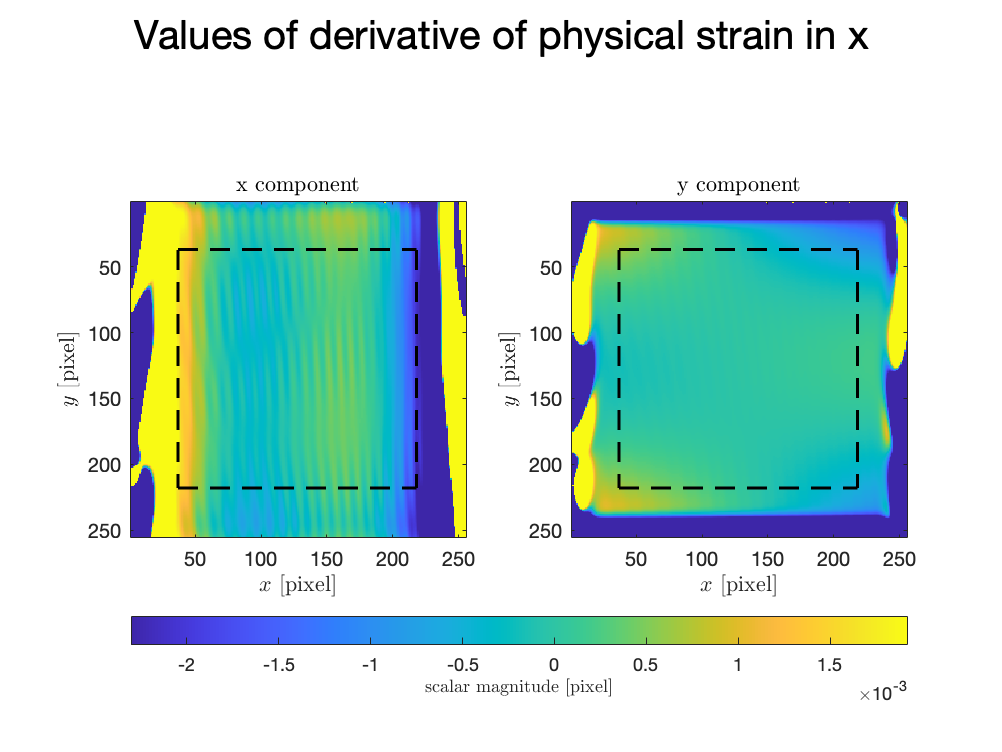

Sxdx = diff(strain(1:end-1,:,1),1,2);
Sxdy = diff(strain(:,1:end-1,1));
Sydx = diff(strain(1:end-1,:,2),1,2);
Sydy = diff(strain(:,1:end-1,2));
convPlot(Sxdx,"derivative of physical strain in x",Sxdy,lambda,zscore);

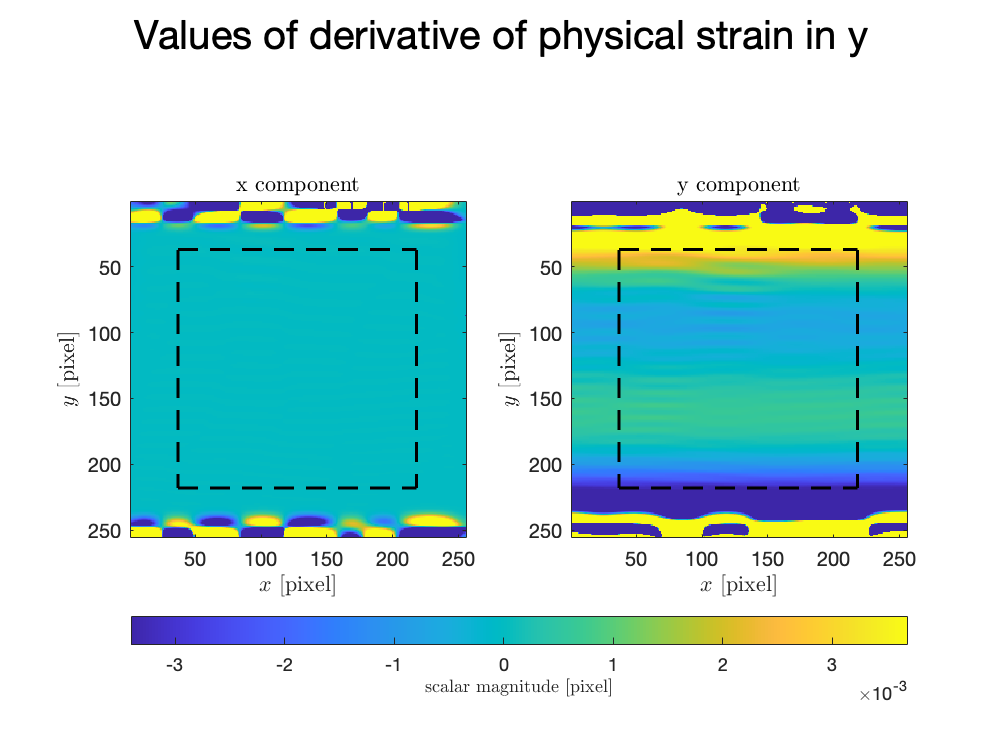

convPlot(Sydx,"derivative of physical strain in y",Sydy,lambda,zscore);

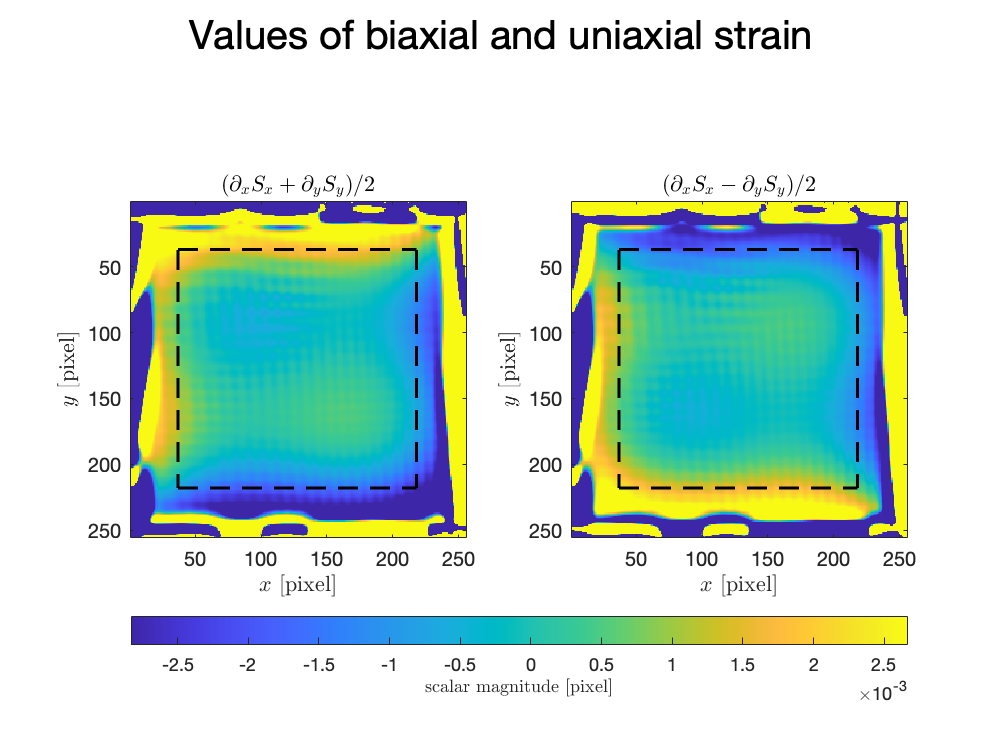

convPlot((Sxdx+Sydy)/2,"biaxial and uniaxial strain",(Sxdx-Sydy)/2,lambda,zscore);